**Simulation of Multiple-Mass Dynamic System**

**Author: Dr. Diane L. Peters**

**School: Kettering University**

Code for Dynamic Systems 1 class: Demonstration of System Simulation

Last updated 6/22/2018 by D. Peters

The objectives for this code are:

- To reinforce students' understanding of linear systems;

- To demonstrate the use of the "lsim" command in MATLAB;

- To allow students the opportunity to experiment with parametric and input changes for the system.

%   Initial clearing of the screen and the memory

clear
clc

Consider a system with two masses, two springs, a damper, and two forces, as shown. In this code, the system will be simulated, to determine how it behaves, and the results will be graphed.

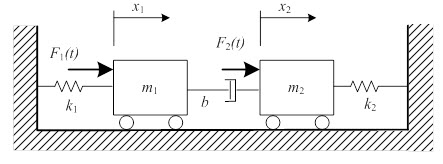

The equations of motion can be derived in several ways - from Newton's Second Law, or from the Lagrangian. They are:

The state-space equations can be developed from these with the states being the original coordinates as well as their derivatives - in other words, the positions and velocities of the masses. They are:

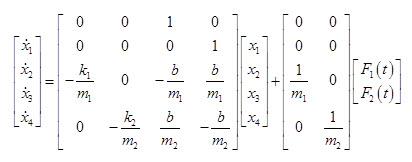

We also need the matrices C and D - in other words, we need to decide what the outputs will be. In this problem, I will choose the outputs to be the position of each mass - in other words, the first two states. (Note that the third and fourth states are the velocity of mass 1 and mass 2, respectively.)

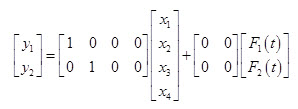

Then, we'll also need the values of the various parameters. Let's use the values   kg,   kg,   N/m,   N/m, and   N-s/m. In the first step in the code, we'll set these values and calculate the matrices A, B, C, and D. (Note that even if D is zero, as it often is, it needs to be specified.)

% Initialization of parameters and calculation of matrices

m1_kg = 1;
m2_kg = 2.5;
k1_N_per_m = 25;
k2_N_per_m = 10;
b_N_s_per_m = 50;

A = [0, 0, 1, 0; 0, 0, 0, 1; -k1_N_per_m/m1_kg, 0, -b_N_s_per_m/m1_kg, b_N_s_per_m/m1_kg; 0, -k2_N_per_m/m2_kg, b_N_s_per_m/m2_kg, -b_N_s_per_m/m2_kg];
B = [0, 0; 0, 0; 1/m1_kg, 0; 0, 1/m2_kg];
C = [eye(2), zeros(2,2)]; % Note that this is an example of using the "eye" command to make a 2 x 2 identity, with a 2 x 2 matrix of zeros next to it.
D = zeros(2,2);

Now, we need to set up the time vector for the simulation, the input(s), and the initial conditions. For the first example, I'm going to set the initial conditions such that the first mass is displaced by 0.5 m, and the second is not displaced. Also in this first example, the inputs will be zero. I'm going to set it up so that the points in the time vector are closely spaced, in order to avoid problems with numerical integration and inaccuracies.

% Setting up the time vector, input forces, and initial conditions for the simulation

time_s = [0:0.01:75];
forces_N = zeros(length(time_s), 2); % This makes a matrix with two columns - one for F1 and one for F2 - and as many rows as we have time points. All zeros.
x0 = [0.5, 0, 0, 0];

Now that we've set up those things, we can run the "lsim" command. We can let it generate a plot directly, or - if we want to have some control over the appearance of the plot - we can make it generate data and then plot that data.

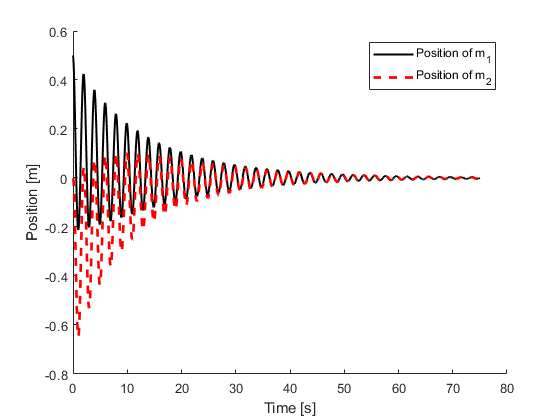

% Simulation of the system and generation of graphs

y = lsim(A, B, C, D, forces_N, time_s, x0); % This data will have two columns, since there are two outputs.

figure(1), clf, hold on, plot(time_s, y(:,1), 'k-', 'LineWidth', 1.5);
figure(1), plot(time_s, y(:,2), 'r--', 'LineWidth', 2), xlabel('Time [s]'), ylabel('Position [m]'), legend('Position of m_1', 'Position of m_2')

Now, let's do the same kind of thing but with zero initial conditions and with some kind of an input forcing function. Let's set one of the forcing functions - the first one - to zero, and make the second one a sine wave with frequency omega. 

% Setting a new set of input forces and initial conditions

omega_rad_per_s = 1.5;
F1 = zeros(length(time_s), 1);
F2 = sin(omega_rad_per_s*time_s);

forces_N = [F1, F2'];
x0 = [0, 0, 0, 0];

Now, we're going to use the same command in the same way, just with these different inputs. Now we can create the second plot.

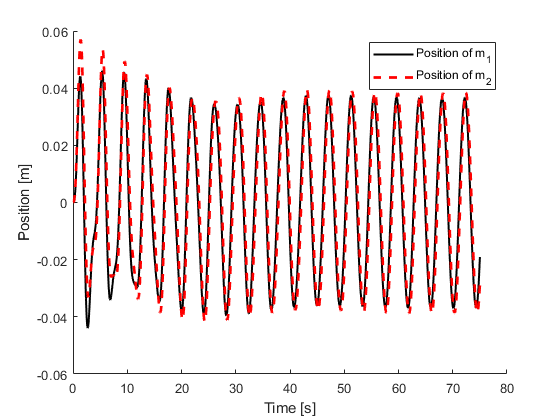

% Simulation and creation of the second graph

y = lsim(A, B, C, D, forces_N, time_s, x0); % This data will have two columns, since there are two outputs.

figure(2), clf, hold on, plot(time_s, y(:,1), 'k-', 'LineWidth', 1.5);
figure(2), plot(time_s, y(:,2), 'r--', 'LineWidth', 2), xlabel('Time [s]'), ylabel('Position [m]'), legend('Position of m_1', 'Position of m_2')

Note that you can set different values for the parameters, or different inputs and initial conditions, in order to explore how this system behaves. The behavior can vary significantly depending on the parameters and the conditions. This is left as an exercise for the student.